# James Holzhauer  vs Ken Jennings

#### Load Data

James = urlread('https://thejeopardyfan.com/statistics/james-holzhauer-jeopardy-statistics');
Ken = urlread('https://thejeopardyfan.com/statistics/ken-jennings-final-statistics');

### Extract Dates

#### James

pattern1 = '<td class="column-2">';
pattern2 = '</td>';
datesJames = extractBetween(James, pattern1,pattern2);
datesJames = datesJames(1:end-1);
gamesJames = (1:length(datesJames))';

#### Ken

datesKen = extractBetween(Ken,pattern1,pattern2);
datesKen = datesKen(1:75);
gamesKen = (1:75)';

### Daily Winnings

#### James

pattern1 = '<td class="column-3">';
pattern2 = '</td>';
JamesWinnings = extractBetween(James,pattern1,pattern2);
JamesWinnings = JamesWinnings(1:end-1);
JamesWinnings = strrep(JamesWinnings, '$', '');
JamesWinnings = strrep(JamesWinnings, ',', '');
JamesWinnings = str2double(JamesWinnings);
JamesCumWin = cumsum(JamesWinnings);

#### Ken

KenWinnings = extractBetween(Ken,pattern1,pattern2);
KenWinnings = KenWinnings(1:75);
KenWinnings = strrep(KenWinnings, '$', '');
KenWinnings = strrep(KenWinnings, ',', '');
KenWinnings = str2double(KenWinnings);
KenCumWin = cumsum(KenWinnings);

### Plot

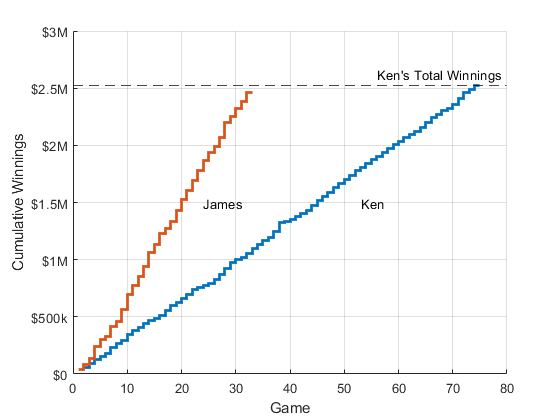

stairs(gamesKen,KenCumWin,'LineWidth',2)
text(53,1500000,'Ken')
hold on
stairs(gamesJames,JamesCumWin,'LineWidth',2)
hold off
text(24,1500000,'James')
xlabel('Game')
ylabel('Cumulative Winnings')
ytickformat('usd')
yline(max(KenCumWin),'k--',"Ken's Total Winnings");
yticks([0 500000 1000000 1500000 2000000 2500000 3000000])
yticklabels({'$0','$500k','$1M','$1.5M','$2M','$2.5M','$3M'})
box off;
ax = gca;
ax.YGrid = "on";
ax.XGrid = 'on';